tspan = [0 10];
Y0 = [0 pi/6 0 5];
[tSol,YSol] = ode45(@Q1ode,tspan,Y0)

tSol =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0003
    0.0004
    0.0005
    0.0007
    0.0014


YSol =          0    0.5236         0    5.0000
    0.0000    0.5237    0.0001    4.9995
    0.0000    0.5239    0.0001    4.9991
    0.0000    0.5240    0.0002    4.9986
    0.0000    0.5242    0.0002    4.9982
    0.0000    0.5249    0.0005    4.9959
    0.0000    0.5256    0.0007    4.9936
    0.0000    0.5263    0.0010    4.9913
    0.0000    0.5270    0.0012    4.9890
    0.0000    0.5306    0.0025    4.9774


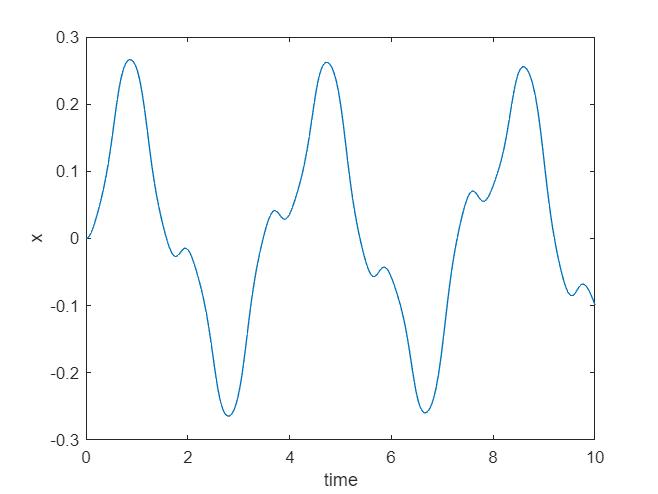


% plot(tSol,YSol)
% legend("x","theta","v","omega")

x = YSol(:,1);
theta = YSol(:,2);
v = YSol(:,3);
omega = YSol(:,4);
x1 = 0.4*sin(theta);
y1 = 0.4*sin(theta);
plot(tSol,x)
ylabel("x")
xlabel("time")

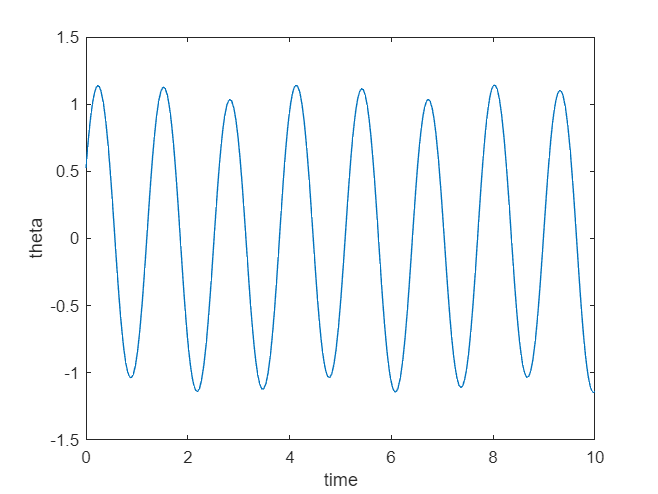


plot(tSol,theta)
ylabel("theta")
xlabel("time")

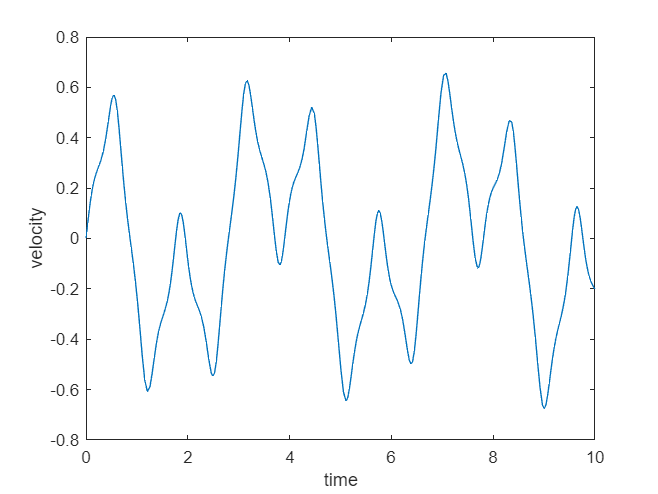


plot(tSol,v)
ylabel("velocity")
xlabel("time")

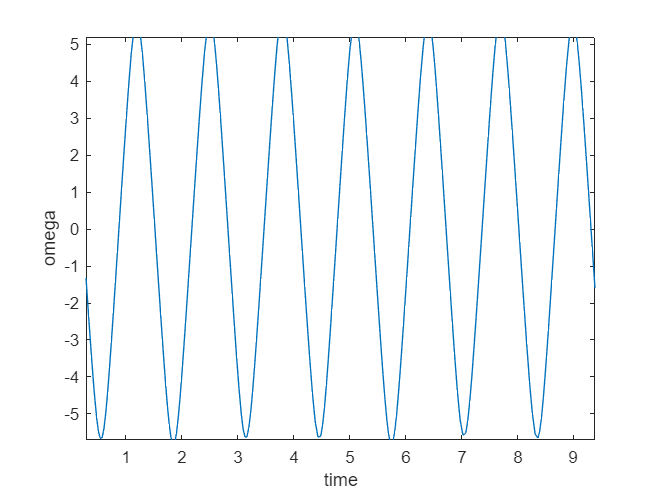


plot(tSol,omega)
ylabel("omega")
xlabel("time")

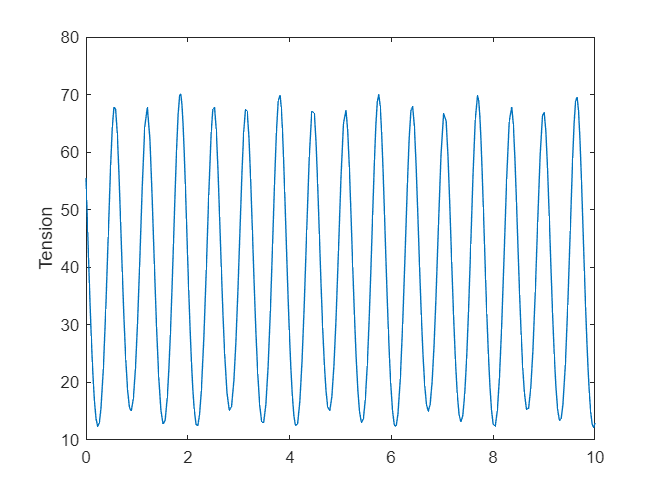


T = 3*(omega.^2)*0.4 + 3*9.81*cos(theta);
plot(tSol,T)
ylabel("Tension")

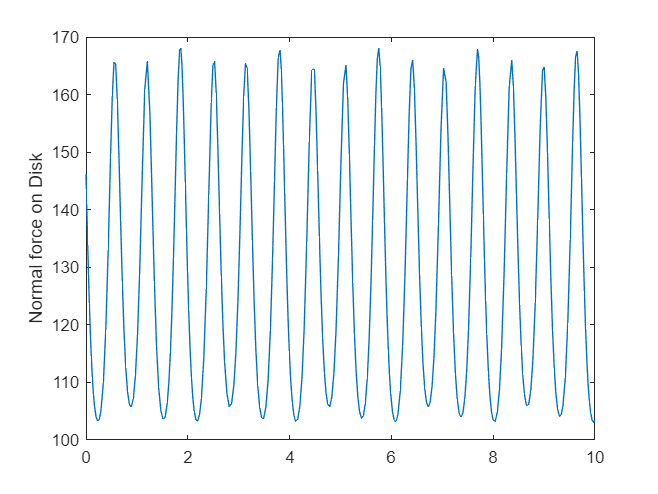


N = 10*9.81 + 3*(omega.^2)*0.4.*cos(theta) + 3*9.81*((cos(theta)).^2);
plot(tSol,N)
ylabel("Normal force on Disk")


tstep = tspan(2)/(length(YSol(:,1))-1)

tstep = 0.0333

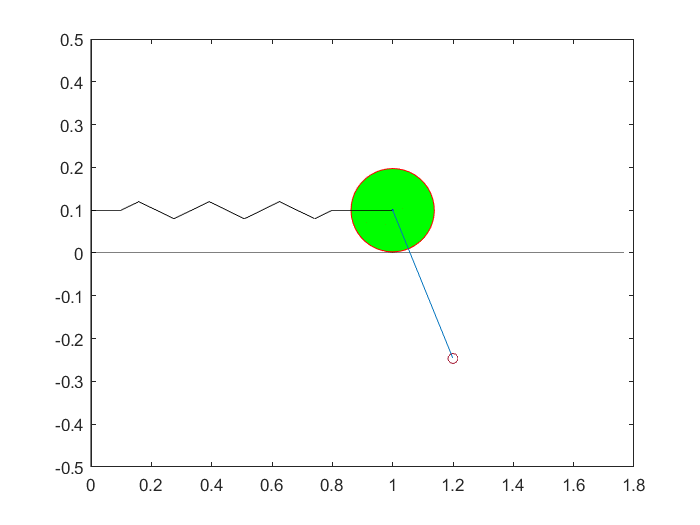

O = [0 0];
P1 = zeros(length(x),2);
P2 = zeros(length(theta),2);
for i = 1:length(x)
    P1(i,:) = [x(i)+1 0.1];
end 

for k = 1:length(x)   
    % Plotting circulas mass
    plot(P1(k,1),P1(k,2),'o','MarkerSize',50,...
    'MarkerEdgeColor','red',...
    'MarkerFaceColor','g')
    hold on

    % Plotting center of mass
    plot(P1(k,1),P1(k,2),'o','MarkerSize',1,...
    'MarkerEdgeColor','blue',...
    'MarkerFaceColor',[0 0 1])
    hold on

    % Plotiing X-axis
    plot([0 (max(P1(:,1))+5*0.1)],[0 0], "Color",'k')
    hold on 

    % Plotting Y-axis
    plot([0 0],[-0.5 5*0.1],"Color",'k')
    hold on

    %plotting spring
    plot([0 0.1],[0.1 0.1],"Color",'k')
    hold on
    ls = P1(k,1) - 0.3;
    plot([0.1 0.1+ls/12],[0.1 0.1+0.02],"Color",'k')
    hold on
    for b = 1:5
        if b/2 == round(b/2)
            v= - 0.02;
        else
            v = 0.02;
        end
        plot([0.1+ls/12+ls/6*(b-1) 0.1+ls/12+ls/6*(b)],[0.1+v 0.1-v],"Color",'k')
        hold on
    end
    plot([0.1+11*ls/12 0.1+ls],[0.1-0.02 0.1],"Color",'k')
    hold on 
    plot([0.1+ls P1(k,1)],[0.1 0.1],"Color",'k')
    
    %plot pendulum
    x1 = 0.4*sin(theta(k)) + P1(k,1);
    y1 = -0.4*cos(theta(k)) + P1(k,2);
    hold on
    plot(x1,y1,'o')
    hold on
    plot([P1(k,1) x1],[P1(k,2) y1])
    hold off
    pause(tstep) 
end

function dYdt = Q1ode(t,Y)
x = Y(1);
theta = Y(2);
v = Y(3);
omega = Y(4);

M = 10;
m = 3;
k = 50;
l = 0.4;
g = 9.81;

dxdt = v;
dthetadt = omega;
dY3dt = ((m*g*cos(theta)*sin(theta)) + (l*m*sin(theta)*(omega^2)) - (k*x))/((m*(sin(theta))^2)+(1.5*M));
dY4dt = ((-cos(theta)/l)*dY3dt) - ((g/l)*sin(theta)); 

dYdt = [dxdt;dthetadt;dY3dt;dY4dt];
end